# Buidl inputs

This is a programmatic way of buidling a smooth signal trace for the PS Lookup Table (1D) block. For a graphical interface, use the Signal Design App which you can find in Project root > Utility > SignalTool.

model_name = "Inputs_Reducer_AxleSide_Flip_refsub";
block_path = "Inputs_Reducer_AxleSide_Flip_refsub/Input torque";

Define a signal design matrix. For details about the signal design matrix, see the description in Project root > Utility > SignalTool.

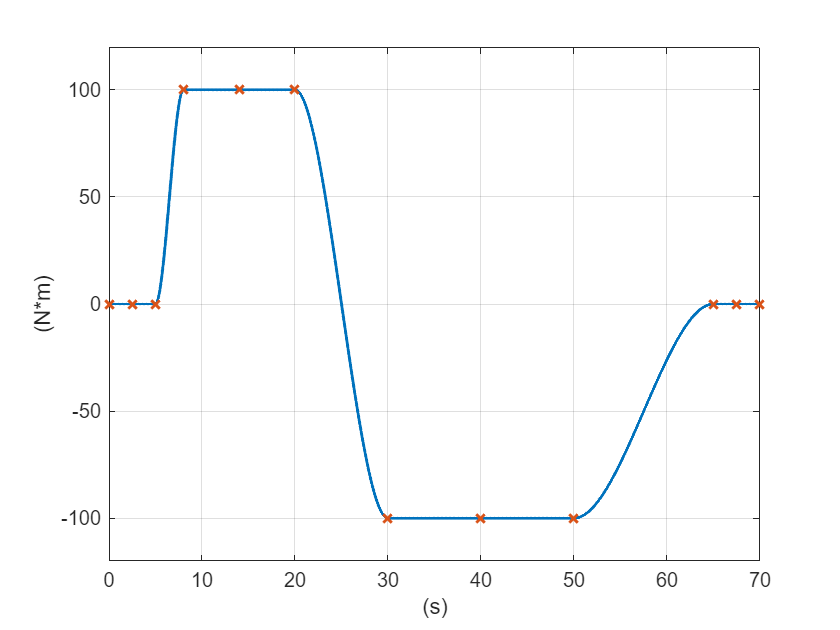

design_matrix = [
  0  5  0
  8  20 100
  30 50 -100
  65 70 0
  ];

result = SignalTool3.getVectorsFromSignalDesignMatrix(design_matrix);
x = result.X';
f = result.F';

% "Table grid vector" parameter in PS Lookup Table (1D) block.
x_text = CodeTool1.stringify(x);
x_unit = "s";

% "Table values" parameter in PS Lookup Table (1D) block.
f_text = CodeTool1.stringify(f);
f_unit = "N*m";

interp_method = "Smooth";
extrap_method = "Nearest";

% Add the design matrix as text to the Description property of the target block.
design_matrix_text = CodeTool1.stringify(design_matrix);

SignalTool3.plotLookupTable1D( ...
  x, f, ...
  XUnitText = x_unit, ...
  YUnitText = f_unit, ...
  Interpolation = interp_method, ...
  Extrapolation = extrap_method, ...
  InterpolationInterval = 0.01, ... for visualization. adjust as needed.
  PlotXLowerBound = x(1), ...
  PlotXUpperBound = x(end) );

Set up the target PS Lookup Table (1D) block.

load_system(model_name)

set_param(block_path, "x", x_text)
set_param(block_path, "x_unit", x_unit);

set_param(block_path, "f", f_text)
set_param(block_path, "f_unit", f_unit);

interp_method = "simscape.enum.interpolation." + lower(interp_method);
set_param(block_path, "interp_method", interp_method)

extrap_method = "simscape.enum.extrapolation." + lower(extrap_method);
set_param(block_path, "extrap_method", extrap_method)

% Add this text to the Description property of the target block.
% Signal Design App extracts text lines between SignalDesignMatrixStart and
% SignalDesignMatrixEnd in a PS Lookup Table (1D) block to get
% the signal design matrix from the block.
description_text = join([
  "% This text was automatically inserted by the Signal Tool."
  "% SignalDesignMatrixStart"
  design_matrix_text
  "% SignalDesignMatrixEnd"
  ], newline);

Uncomment the code below to update the target block. Note that it erases the current settings in the block.

%{
set_param(block_path, "Description", description_text)
%}

*Copyright 2025-2026 The MathWorks, Inc.*